# ASTE 524 HW4

R = 6378; %km
h_e = 122; %km
r_e = R + h_e; %km
g = 9.8e-3; %km/s^2
beta = 0.1354; %1/km
rho_s = 1.225e9; %kg/km^3
rho = @(h) rho_s*log(-beta*h); %kg/km^3

## Problem 1

The shuttle orbiter used variations in angle of attack to control L/D during entry, but for the high-speed phase of entry, we can assume a constant L/D=1.05. Let us define the completion of the high-speed entry phase as occuring at 25-km altitude and 750 m/s velocity. Assuming the $\gamma_e=-1.2^{\circ}$ and $v_e=7.5\frac{km}{s}$.

LD_ratio = 1.05;
gamma_e = -1.2; %deg
v_e = 7.5; %km/s

### Part A

What is the approximate range from entry interface to terminal phase initiation?

s = 1/2*R*LD_ratio*log(1/(1-v_e^2/(g*R))) %km

s = 7.7080e+03


$$s=7,708.0km$$


### Part B

What is the peak $g$ experienced during the high-speed entry phase and what point in the trajectory does it occur?

v = 0.75; %km/s
a = (v^2/(g*R)-1)/LD_ratio %g

a = -0.9438


$$a=-0.94g$$
 

The peak $g$ occurs at the completion of the high-speed entry phase.

### Part C

What is the approximate shuttle orbiter cross-range capability using this constant L/D?

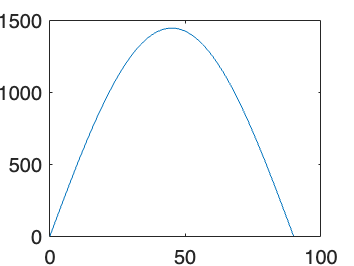

sigma = linspace(0,90,100); %deg
cross_range = @(sigma) R*pi^2/48*LD_ratio^2*sind(2*sigma); %km
plot(sigma,cross_range(sigma))

cross_range(45)

ans = 1.4458e+03


$$s_{\perp}=1,445.8km$$


### Extra Credit:

Using the equation on Slide 31 of Lecture 4 notes, we can calculate the cross-range distance for the space shuttle orbiter, which has ~1.3 L/D ratio. why was this cross-range capability desirable for NASA?

LD_ratio = 1.3;
sigma = 45;
cross_range = R*pi^2/48*LD_ratio^2*sind(2*sigma)

cross_range = 2.2163e+03

The larger cross-range capability, $2,216.3km$, was desirable to NASA for the space shuttle orbiter since they used banking turns in the final portion of the decent in order to slow the shuttle for landing.

## Problem 2

Given the following Gemini vehicle parameters:

m = 2200; %kg
v_e = 7.5; %km/s
S = 4.1; %m^2
C_D = 1.5;
LD_ratio = 0.19;

### Part A

Assuming a ballistic entry, with an entry flight path of $\gamma_e=-5^{\circ}$ what would be the maximum entry acceleration and at what altitude would this max accel occur?

gamma_e = -5; %deg
a = (beta*v_e^2)/(2*exp(1))*sind(gamma_e)/g %g

a = -12.4591

h_crit = 1/beta*log(-1/beta*S*C_D/m*rho_s/sind(gamma_e)) %km

h_crit = 143.9145


$$a=-12.46g$$



$$h_{crit}=143.91km$$


### Part B

Assuming a lifting entry with an entry flight path angle of $\gamma_e=-2^{\circ}$ that completes at a velocity of $750\frac{m}{s}$, what is the peak $g$ experienced during the high-speed entry phase and what point in the trajectory does it occur?

gamma_e = -2; %deg
v = 0.75; %km/s
a = (v^2/(g*R)-1)/LD_ratio %g

a = -5.2158


$$a=-5.22g$$


The peak $g$ occurs at the completion of the high-speed entry phase.

### Part C

Assuming a lifting entry with an entry flight path angle of $\gamma_e=-2^{\circ}$, what was the total range from entry interface to landing?

s = 1/2*R*LD_ratio*log(1/(1-v_e^2/(g*R))) %km

s = 1.3948e+03


$$s=1,394.8km$$


### Part D

Assuming a lifiting entry with an entry flight path angle of $\gamma_e=-2^{\circ}$, what was the maximum cross-range capability?

sigma = 45; %deg
cross_range = R*pi^2/48*LD_ratio^2*sind(2*sigma) %km

cross_range = 47.3424


$$s_{\perp}=47.34km$$


## Problem 3

It is desired to have a simple, fail-safe crew emergency return vehicle for use on the Artemis lunar space station, Gateway. The program manager edicts that, to minimize cost and complications, a basic ballistic entry vehicle will be used. However, the entry g-load is required by medical authorities to be $8g$ or less.

### Part A

If $11\frac{km}{s}$ (air relative), is this possible? What is the maximum absolute value of entry flight path angle?

v_e = 11; %km/s
a = 8; %g
c = (beta*v_e^2)/(2*exp(1));
gamma_e = asind(a*g*1/c) %deg

gamma_e = 1.4908

It could be possible, as long as $|\gamma_e| \lt 1.49^{\circ}$. However, these equations become questionable when $|\gamma_e|\lt 5^{\circ}$.

### Part B

Assuming it is possible to design a balistic entry vehicle with no lift and can maintain a constant $|\gamma_e| \lt 1.49^{\circ}$ then it could be created. However, since the entry flight path angle is so shallow, it is likely that as the entry vehicle entered further into the atmosphere the flight path angle would start to get larger and the g-load would exceed the maximum allowable. 